## 分析耦合项对姿态换或者主轴环的影响

clc

ulogOBJ = ulogreader("HILSimData\stable\log_1_2021-6-30-08-01-44.ulg");
msg = readTopicMsgs(ulogOBJ);

## 滤波姿态

attitude = msg.TopicMessages{35};
attitude_time = attitude.timestamp;
q = attitude.q;
maxi = size(q,1);

## 主轴n3

for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_1 = N3(:,3);
clear N3 attitude attitude_time q


ulogOBJ = ulogreader("HILSimData\stable\log_0_2021-6-30-08-03-24.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{31};
attitude_time = attitude.timestamp;
q = attitude.q;
maxi = size(q,1);

for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_2 = N3(:,3);

clc
clear N3 attitude attitude_time q

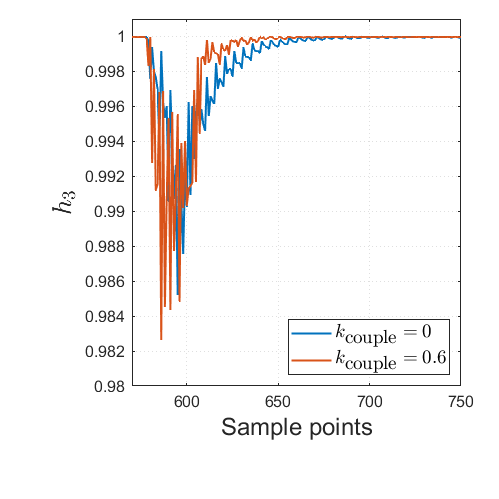

figure(7)
plot(h3_1(73:1711),'LineWidth',1.5)
hold on
plot(h3_2(1:1639),'LineWidth',1.5)
ylim([0.98,1.001])
xlim([570,750])
legend('$k_{\textrm{couple}}=0$','$k_{\textrm{couple}}=0.6$','Interpreter','latex',"FontSize", 14)
ylabel('$h_3$','Interpreter','latex',"FontSize",20)
xlabel('Sample points',"FontSize",18)